# MHKiT SWAN Example

This example notebook demonstrates the input and plotting of output data from the software [Simulating WAves Nearshore (SWAN)](http://swanmodel.sourceforge.net/) using MHKiT. In this example the [SNL-SWAN](https://github.com/SNL-WaterPower/SNL-SWAN) tutorial was run for a wave energy converter. The output was written in ASCII and binary (*.mat) files. This MHKiT example notebook demonstrates how to import these different files into MHKiT and plot the output data.

## Supported SWAN Output Files

MHKiT currently supports block and table SWAN output files in ASCII or binary (*.mat) files. Detailed descriptions of these file types may be found in the [SWAN User Manual](http://swanmodel.sourceforge.net/download/zip/swanuse.pdf). In the following cells, SWAN table and block data will be imported, discussed, and plotted. Three SWAN output files will be imported:

- An ASCII table file ('SWANOUT.DAT'),

- An ASCII block file ('SWANOUTBlock.DAT')

- A binary block file ('SWANOUT.mat')

swan_path = "./examples/data/wave/SWAN/";
swan_table_file = append(swan_path,"SWANOUT.DAT");
swan_block_file = append(swan_path,"SWANOUTBlock.DAT");
swan_block_mat_file = append(swan_path,"SWANOUT.mat") ;

## Load SWAN Files with MHKiT

To load a supported non .mat SWAN file simply call the `swan_read_table` or `swan_read_block` as appropriate for the swan output. The MHKiT function will read in the SWAN output and return the data as a structure. The structure will also contain any metadata that the file may contain which will vary based on the file type and options specified in the SWAN run. MHKiT requires that for block data written in ASCII format that the file was written with headers. The `swan_read_block` function accepts both binary and ASCII format by assuming that any non-'.mat' extension is ASCII format.

## SWAN Table Data and Metadata

The SWAN output table is parsed from the MHKiT function `swan_read_table` into a structure that is displayed below. The structure fields contain a series of x-points ('Xp'), y-points ('Yp'), and keyword values at a given (x,y) point. The keywords are specified in the SWAN user manual and here can be seen as: 'Hsig' (significant wave height), 'Dir' (average wave direction), 'RTpeak' (Relative peak period), 'TDir' (direction of the energy transport).

swan_table = swan_read_table(swan_table_file)

swan_table = struct with fields:
          Xp: [10201×1 double]
          Yp: [10201×1 double]
        Hsig: [10201×1 double]
         Dir: [10201×1 double]
      RTpeak: [10201×1 double]
        TDir: [10201×1 double]
       units: [1×1 struct]
    metadata: [1×1 struct]


In the cell below, metadata is written to screen and can be seen to be a structure of keywords which contains the SWAN run name, the type of table written, and the version of SWAN run. The units show the column headers, and the associated units.

swan_table.metadata

ans = struct with fields:
        Run: "TEST"
      Table: "COMPGRID"
    version: "41.20"


swan_table.units

ans = struct with fields:
        Xp: "[m]"
        Yp: "[m]"
      Hsig: "[m]"
       Dir: "[degr]"
    RTpeak: "[sec]"
      TDir: "[degr]"


## SWAN Block (ASCII) Data and Metadata

MHKiT will read in block data as a structure. The structure swan_block (shown below) is read using `swan_read_block` on the ASCII block data, and has the same four keys from the table data shown previously. In the cell below the structure for the 'Significant_wave_height' is shown by using the specified key. This structure has the metadata for Significant_wave_height. The last line of code looks at the values from Significant_wave_height. This matrix has a value of significant wave height at each point on the modeled output grid.

swan_block = swan_read_block(swan_block_file);
swan_block.Significant_wave_height

ans = struct with fields:
            values: [101×101 double]
               Run: "TEST"
             Frame: "COMPGRID"
              Unit: "0.1000E-01 m"
    unitMultiplier: 0.0100


swan_block.Significant_wave_height.values

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1 

## SWAN Block (.mat) Data and Metadata

Reading in SWAN .mat data files is as simple as loading the file into the Matlab workspace.

swan_block_mat = load(swan_block_mat_file)

swan_block_mat = struct with fields:
      Hsig: [101×101 single]
       Dir: [101×101 single]
    RTpeak: [101×101 single]
      TDir: [101×101 single]


## Example Plots from SWAN Data

This last section shows a couple of plots for the significant wave height using each of the imported results. Plot Table Data To plot 1D vector data, we must grid the swan data to make a 2D matrix. We do this by first creating xx and yy vectors spanning the x and y dimensions. We use meshgrid to create a 2D mesh. Finally we grid the Hsig data to the mesh.

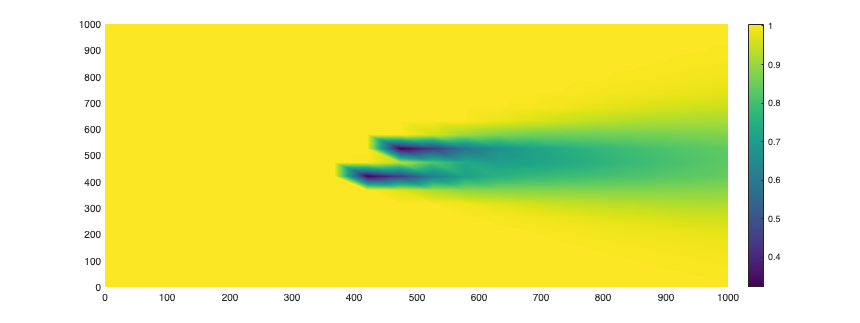

xx = linspace(min(swan_table.Xp),max(swan_table.Xp),20);
yy = linspace(min(swan_table.Yp),max(swan_table.Yp),20);
[X,Y] = meshgrid(xx,yy);
Z = griddata(swan_table.Xp,swan_table.Yp,swan_table.Hsig,X,Y);
figure('Position', [100, 100, 1600, 600]);
plot_table = pcolor(X,Y,Z); % Note: you should include X,Y coordinates
shading interp;
colormap(viridis_colormap(256)); % Default MATLAB colormap
colorbar; % Add a colorbar to show the scale


% Plotting SWAN block data

figure('Position', [100, 100, 1600, 600]);
colormap(viridis_colormap(256));
plot_block = pcolor(swan_block.Significant_wave_height.values)

plot_block =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 … ] (1×101 double)
           YData: [101×1 double]
           ZData: [101×101 double]
           CData: [101×101 double]

  Show all properties


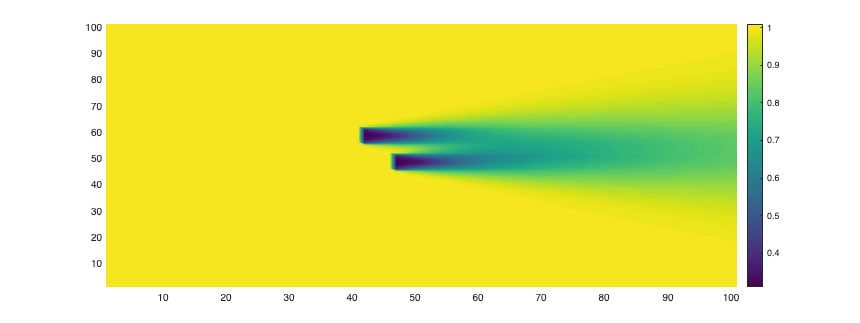

shading interp;
colorbar;